# Non-Maxima supression on object detecion

It's a method used on object detection to ignore redundant overlapping bounding boxes, during prediction.

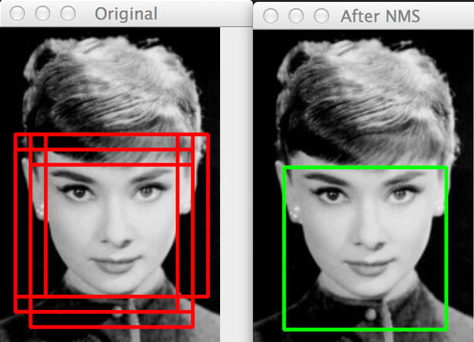

## Example

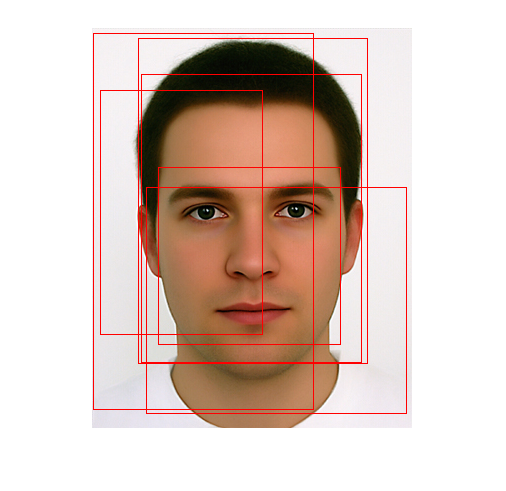

imgFace = imread('learn/MatLiveScripts/imgs/AverageFace.jpg');
% Boxes on format [x,y,width,height]
% I got those boxes with the train image labeler app from mathworks
b1 = [55	160	261	227];
b2 = [2	6	221	377];
b3 = [50	47	221	289];
b4 = [47	11	230	326];
b5 = [9	63	163	245];
b6 = [67	140	183	178];
IoUThreshold = 0.6;
% Merge boxes
bboxes = [b1;b2;b3;b4;b5;b6];
%bboxes = [b3];

RGB = insertShape(imgFace,'Rectangle',bboxes,'Color','red');
imshow(RGB);

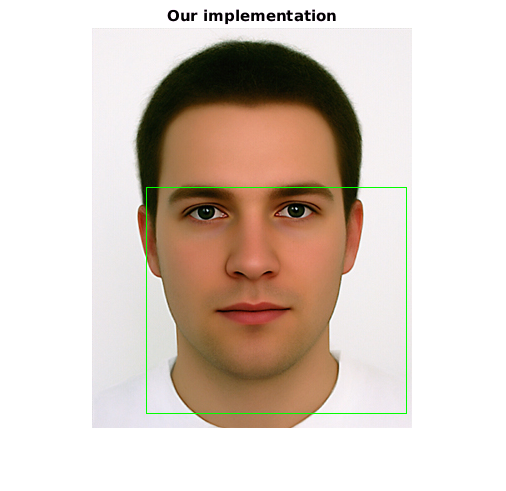

boxfiltred = fastNonMaximaSupression(bboxes,IoUThreshold);
boxfiltred_ref_slow = nms_slow(convert_rect_type(bboxes), IoUThreshold);
boxfiltred_ref_fast = nms_fast(convert_rect_type(bboxes), IoUThreshold);
RGB = insertShape(imgFace,'Rectangle',boxfiltred,'Color','green');
imshow(RGB);
title('Our implementation');

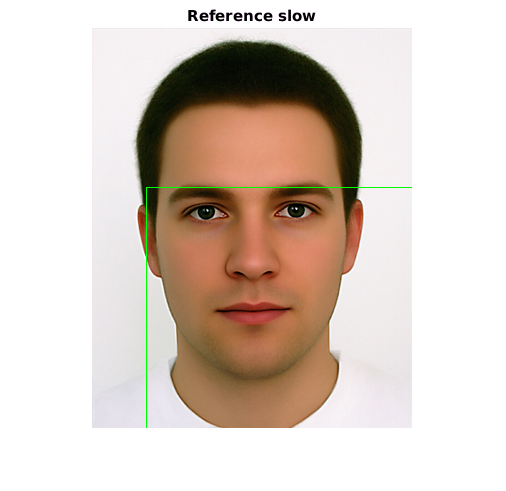

RGB = insertShape(imgFace,'Rectangle',boxfiltred_ref_slow,'Color','green');
imshow(RGB);
title('Reference slow');

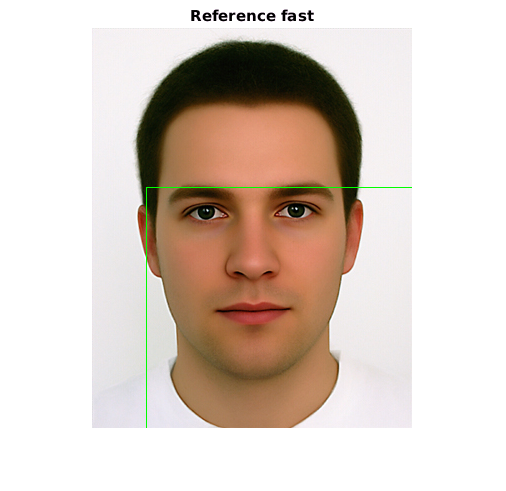

RGB = insertShape(imgFace,'Rectangle',boxfiltred_ref_fast,'Color','green');
imshow(RGB);
title('Reference fast');

## References

- [Tutorial in Python](http://www.pyimagesearch.com/2014/11/17/non-maximum-suppression-object-detection-python/)

- [Tutorial in Python (Faster)](http://www.pyimagesearch.com/2015/02/16/faster-non-maximum-suppression-python/)

- [Example code in Matlab](https://github.com/quantombone/exemplarsvm/blob/54c07ec4faa96fb949991ebc512eaf7446e034f7/internal/esvm_nms.m)

- [Gist Reference for fast_nms](https://gist.github.com/quantombone/1144423)

- [Mathworks example slow_nms](https://uk.mathworks.com/matlabcentral/fileexchange/47020-pictorial-suspicious-action-detection/content/suspiciousactivitydetector-master/code/voc-release3.1/voc-release3.1/nms.m)

- [Other Matlab Example](http://www.computervisionblog.com/2011/08/blazing-fast-nmsm-from-exemplar-svm.html)

- [Hog+SVM object detection](http://www.pyimagesearch.com/2014/11/10/histogram-oriented-gradients-object-detection/)

- [SVM Object detection](http://www.cs.cmu.edu/~tmalisie/projects/iccv11/index.html)

- [Video about Hog object detection](https://www.youtube.com/watch?v=7S5qXET179I)

- [Pedestrian Detection Wikipedia](https://en.wikipedia.org/wiki/Pedestrian_detection)

- [Object Detection with Fast-R-CNN](https://github.com/Microsoft/CNTK/wiki/Object-Detection-using-Fast-R-CNN#NMS-Non-Maximum-Suppression)

- [Tomasz Malisiewicz](http://people.csail.mit.edu/tomasz/)

- [Hog Visualizer](http://web.mit.edu/vondrick/ihog/)